## Exercise 1

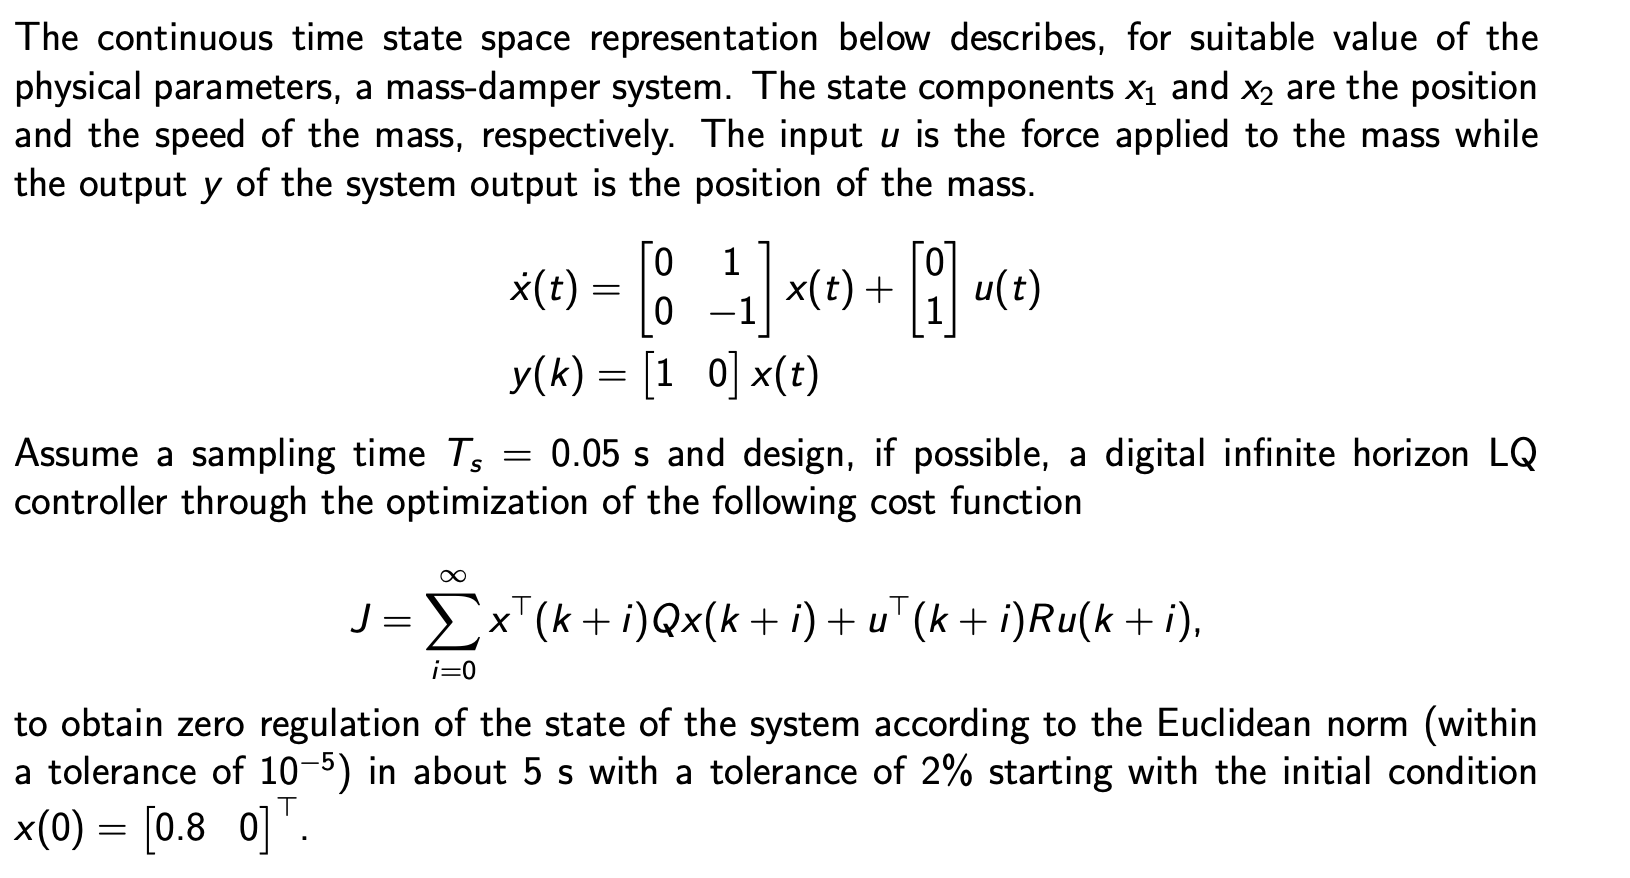

close all
clear
clc

A = [0 1; 0 -1];
B = [0;1];
C = [1 0];
D = 0;
x0 = [0.8; 0];

Ts = 0.05;

sys = ss(A,B,C,D);

sys_dt = c2d(sys,Ts, 'zoh');

Ad = sys_dt.A

Ad =     1.0000    0.0488
         0    0.9512


Bd = sys_dt.B;
Cd = sys_dt.C;

Mr = ctrb(Ad,B);
rho_Mr = rank(Mr)

rho_Mr = 2


% define Q and R
Q = eye(2);
R = 1;

Cq = chol(Q);
Mo = obsv(Ad,Cq);
rho_Mo = rank(Mo)

rho_Mo = 2


% Define the state feedback gain matrix K using LQR
K = dlqr(Ad, Bd, Q, R)

K =     0.9753    0.9752


Now we have to simulate 

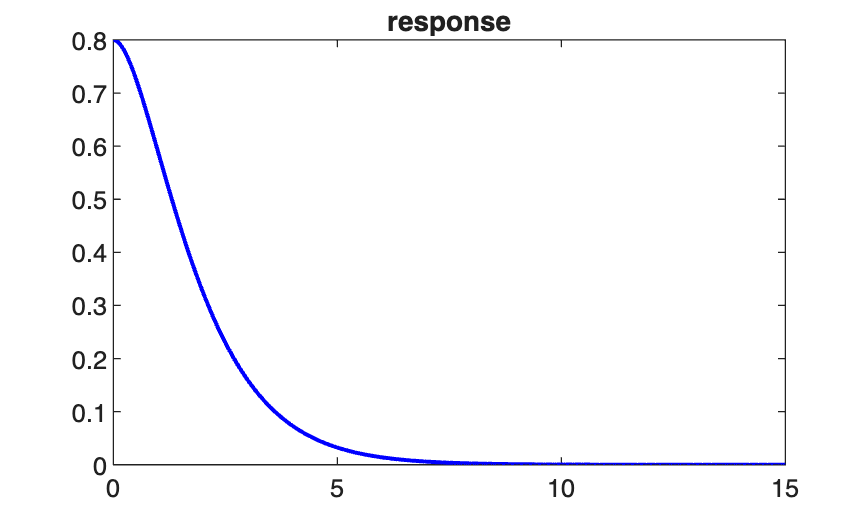

Tend = 15;
sys_x = ss(A,B,eye(size(C,2)), 0);

out = sim("LAB4_primoEs.slx");

y = out.y;
x = out.x;

figure
plot(y.time,y.data,'b', 'LineWidth',1.5);
title("response")

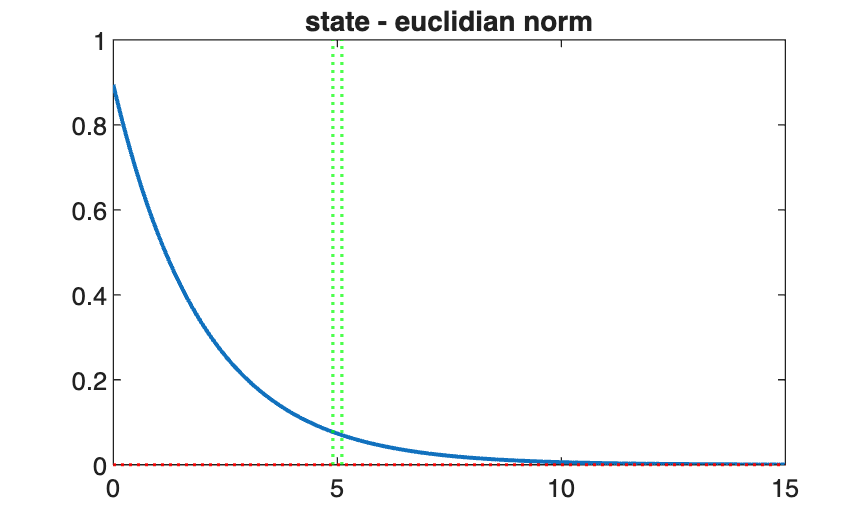


% develop euclidian norm
x_norm = zeros(length(x.data),1);
for ii=1:size(x.data,2)
    x_norm = x_norm + x.data(:,ii);
end
x_norm = sqrt(x_norm);

figure
plot(x.time, x_norm, 'LineWidth',1.5);
title("state - euclidian norm")
yline(1e-5, ':r', 'LineWidth',1.2)
yline(-1e-5, ':r', 'LineWidth',1.2)
xline(5+0.02*5, ':g', 'LineWidth',1.2)
xline(5-0.02*5, ':g', 'LineWidth',1.2)

#### Tuning

In order to satisfy our requirements, we must change Q values, in particular we must have a faster response

The second state has zero initial condition, so let's start working on state 1 (changing Q(1,1))

Then let's tune a bit also R (for the meme)

R = 1.5;
Q = [100, 0; 0 1];
Cq = chol(Q);
Mo = obsv(Ad,Cq);
rho_Mo = rank(Mo)

rho_Mo = 2

K = dlqr(Ad, Bd, Q, R);

Now let's simulate again

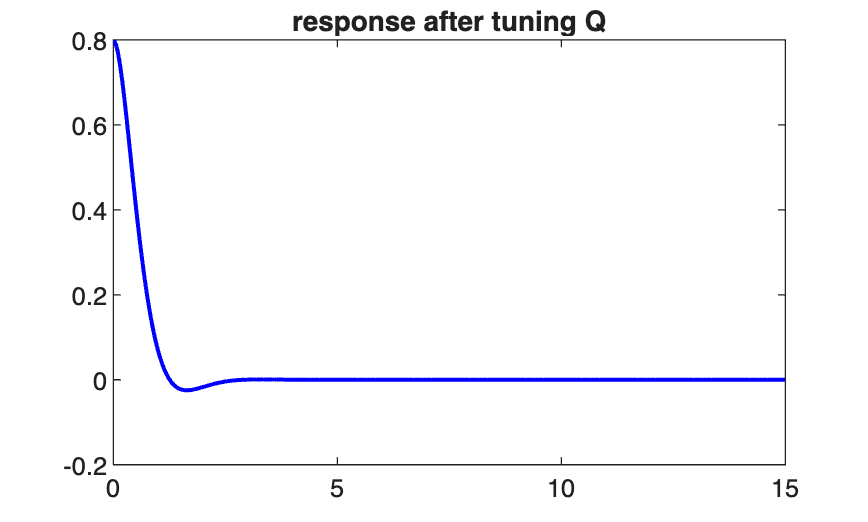

clear out

out = sim("LAB4_primoEs.slx");

y = out.y;
x = out.x;

figure
plot(y.time,y.data,'b', 'LineWidth',1.5);
title("response after tuning Q")


% develop euclidian norm
x_norm = zeros(length(x.data),1);
for ii=1:size(x.data,2)
    x_norm = x_norm + x.data(:,ii);
end
x_norm = sqrt(x_norm);

figure
plot(x.time, x_norm, 'LineWidth',1.5);

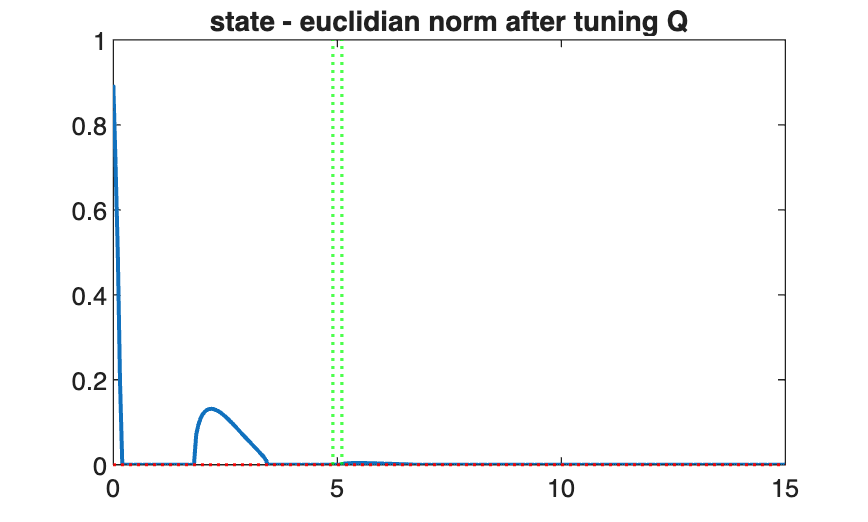

title("state - euclidian norm after tuning Q")
yline(1e-5, ':r', 'LineWidth',1.2)
yline(-1e-5, ':r', 'LineWidth',1.2)
xline(5+0.02*5, ':g', 'LineWidth',1.2)
xline(5-0.02*5, ':g', 'LineWidth',1.2)

## Exercise 2

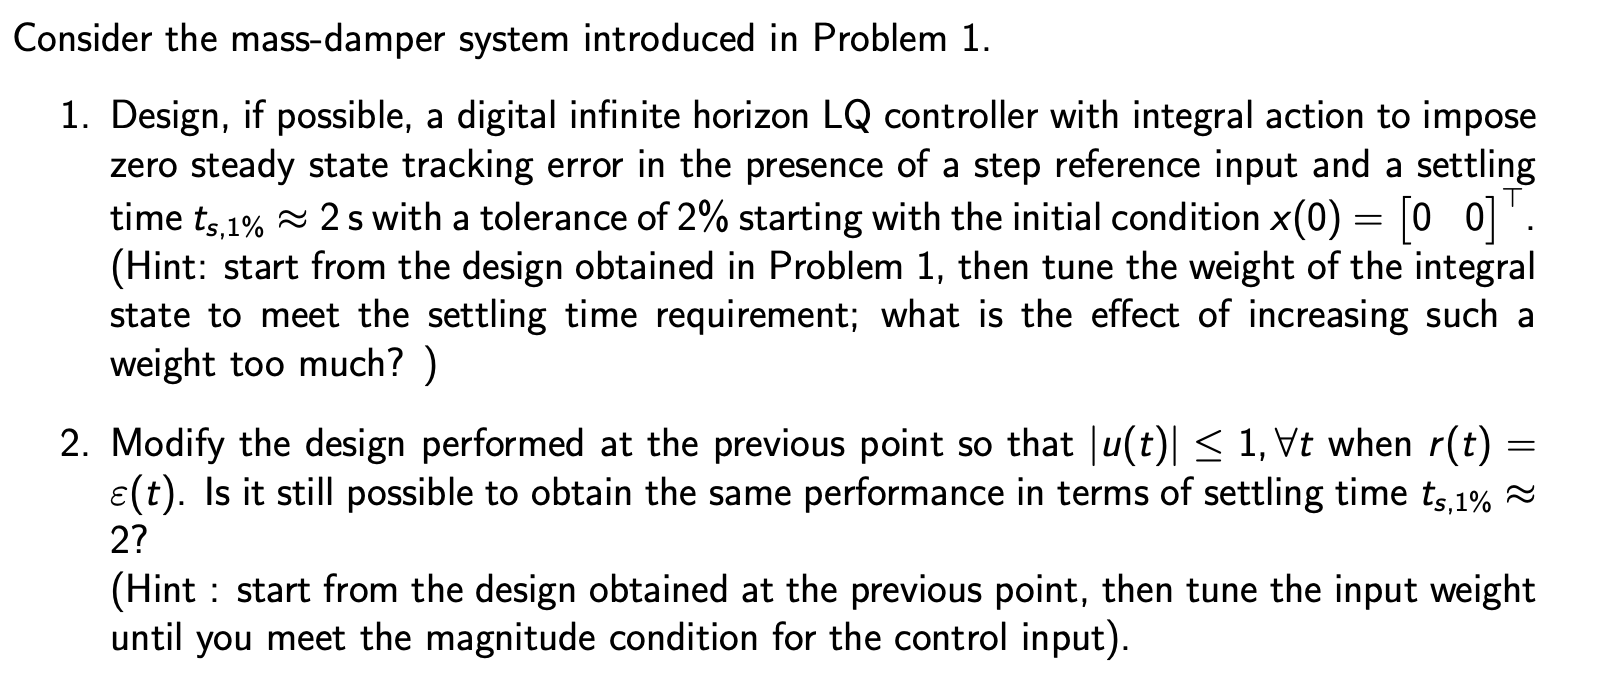

For completeness, let's recompute everything (also the common variables)

close all
clear
clc
A = [0 1; 0 -1];
B = [0;1];
C = [1 0];
D = 0;
x0 = [0; 0]; % different initial state than before

Ts = 0.05;

sys = ss(A,B,C,D);

sys_dt = c2d(sys,Ts, 'zoh');

Ad = sys_dt.A

Ad =     1.0000    0.0488
         0    0.9512


Bd = sys_dt.B;
Cd = sys_dt.C;

Mr = ctrb(Ad,B);
rho_Mr = rank(Mr)

rho_Mr = 2

Now, before to go on, we must define our augmented system (see from theory)

Aaug = [1 -Ts*Cd; zeros(2,1) Ad];
Baug = [0; Bd];
Caug = [0 Cd];
Daug = 0;
x0i = 0; % integrator initial condition

Now let's define our matrices Q and R, let's start with unitary weights

Q = diag(ones(1,size(Aaug,1)));
R = 1;
Cq = chol(Q);
Mo = obsv(Aaug,Cq);
rho_Mo = rank(Mo)

rho_Mo = 3

And now let's compute K

Kaug = dlqr(Aaug,Baug,Q,R);

% we have to split the control gain K
% (q is a scalar, so k_q is a scalar to. k_x is all the remaining
% components of Kaug)

K_q = Kaug(1);
K_x = Kaug(2:end);

Now we can simulate

This time, we don't have requirements on the state euclidian norm, instead, we have setting time requirements.

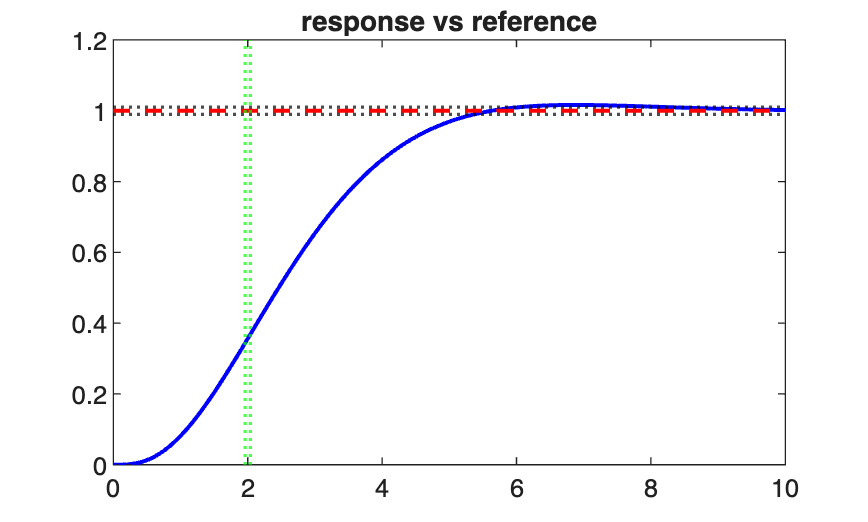

Tend = 10;
sys_x = ss(A,B,eye(size(C,2)), 0);
step_value = 1;
settling_time = 2;

out = sim("LAB4_secondoEs.slx");

y = out.y;
x = out.x;
r = out.r;
u1 = out.u;

figure
plot(y.time,y.data,'b', 'LineWidth',1.5);
hold on 
plot(r.time,r.data,'r--', 'LineWidth',1.5)
title("response vs reference")

yline(step_value+0.01*step_value, ':k', 'LineWidth',1.2)
yline(step_value-0.01*step_value, ':k', 'LineWidth',1.2)
xline(settling_time+0.02*settling_time, ':g', 'LineWidth',1.2)
xline(settling_time-0.02*settling_time, ':g', 'LineWidth',1.2)

From the plot we clearly see that we need a faster response (ie we must increase Q values) -> we have to track our response faster!!

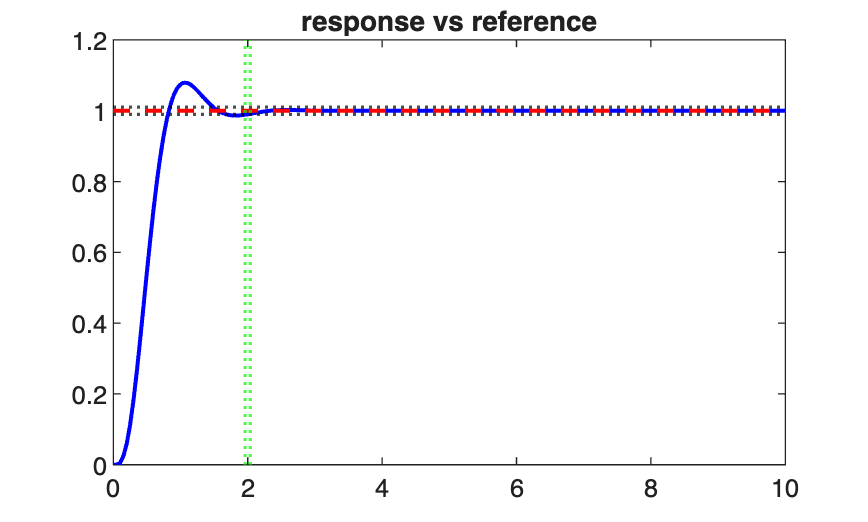

clear out

Q(1,1) = 2e4;
R = 1.7;

Cq = chol(Q);
Mo = obsv(Aaug,Cq);
rho_Mo = rank(Mo);

Kaug = dlqr(Aaug,Baug,Q,R);

K_q = Kaug(1);
K_x = Kaug(2:end);

out = sim("LAB4_secondoEs.slx");

x = out.x;
u2 = out.u;
y = out.y;
r = out.r;

figure
plot(y.time,y.data,'b', 'LineWidth',1.5);
hold on 
plot(r.time,r.data,'r--', 'LineWidth',1.5)
title("response vs reference")

yline(step_value+0.01*step_value, ':k', 'LineWidth',1.2)
yline(step_value-0.01*step_value, ':k', 'LineWidth',1.2)
xline(settling_time+0.02*settling_time, ':g', 'LineWidth',1.2)
xline(settling_time-0.02*settling_time, ':g', 'LineWidth',1.2)

Since we had to increase Q value, we expect that the control input will increase a lot between the two plot.

We can visualise it in the next figure

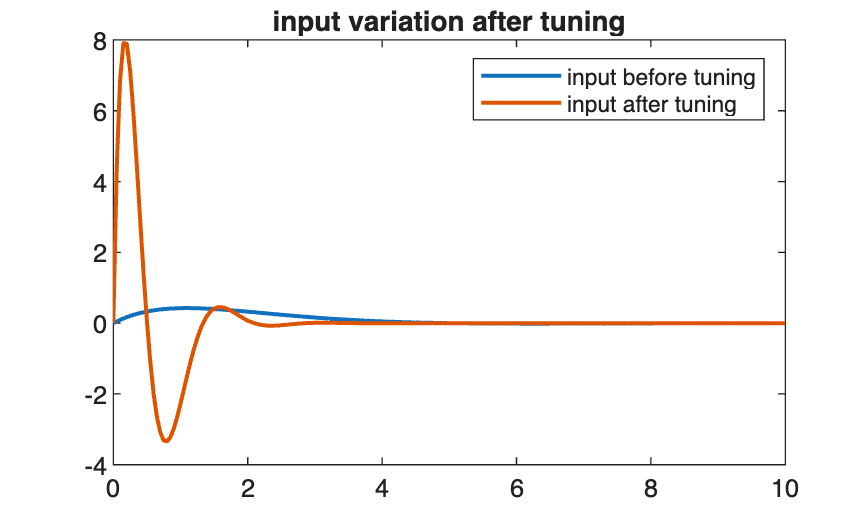

figure
plot(u1.time,u1.data, "LineWidth",1.5);
hold on
plot(u2.time,u2.data, "LineWidth",1.5);
legend("input before tuning", "input after tuning")
title("input variation after tuning")

As we can see, the input increment is huge.

Now we want to limit it, in particular we want that u(t) is less than 1 for any t => we must increase R until we satisfy this behaviour

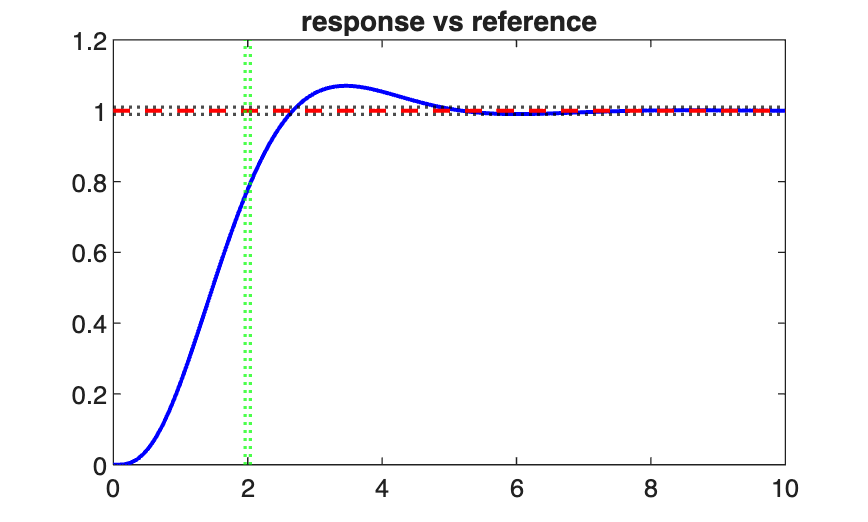

clear out

R = 1700;

Kaug = dlqr(Aaug,Baug,Q,R);

K_q = Kaug(1);
K_x = Kaug(2:end);

out = sim("LAB4_secondoEs.slx");

x = out.x;
u = out.u;
y = out.y;
r = out.r;

figure
plot(y.time,y.data,'b', 'LineWidth',1.5);
hold on 
plot(r.time,r.data,'r--', 'LineWidth',1.5)
title("response vs reference")

yline(step_value+0.01*step_value, ':k', 'LineWidth',1.2)
yline(step_value-0.01*step_value, ':k', 'LineWidth',1.2)
xline(settling_time+0.02*settling_time, ':g', 'LineWidth',1.2)
xline(settling_time-0.02*settling_time, ':g', 'LineWidth',1.2)

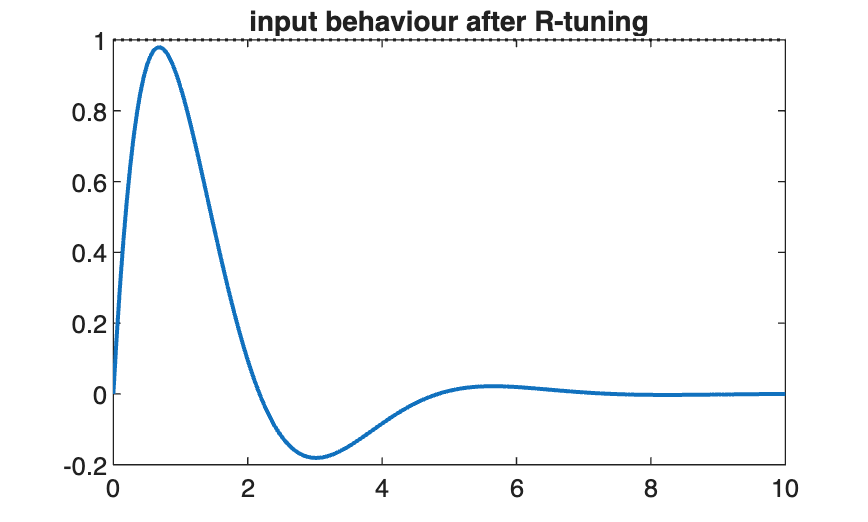


figure
plot(u.time,u.data, "LineWidth",1.5);
title("input behaviour after R-tuning")
yline(1, ':k', 'LineWidth',1.2)